# indentPlot

This live script is continuation of calciumPlot.mlx and applied to the indentation stimuli

#### Load the indenter stimulation file

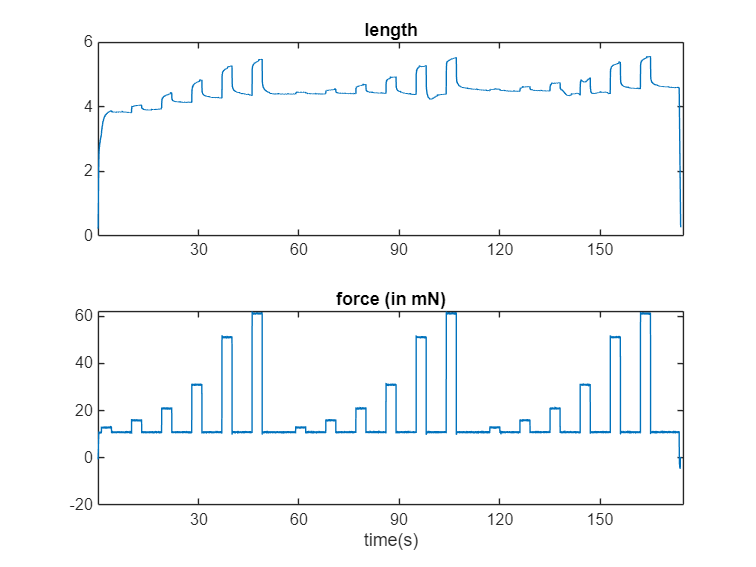

folderNameTemp = strsplit(path,filesep);
folderName = folderNameTemp{end-1};
clear folderNameTemp
[filenameMat,pathMat] = uigetfile('\\research.files.med.harvard.edu\Neurobio\GintyLab\Qi\stimulation\indenter\*.mat',...
    ['select an indentation file for   ', folderName]);

% [filenameMat,pathMat] = uigetfile('C:\Users\Qi_Li\Dropbox (HMS)\LQCalciumImaging\stimulation\indenter\*.mat', ...
%     ['select an indentation file for
load([pathMat,filenameMat])
force = data(:,3);
down = 10;
figure,
tick = floor(numel(force)/Fs/5/10)*10;
% subplot(311),plot(cameraTrigger(1:10:end)),title('Trigger'),
subplot(211),plot(data(1:down:end,2)),title("length");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
subplot(212),plot(data(1:down:end,3)*50),title("force (in mN)");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
xlabel('time(s)')

% plot(force),title("force")
% pbaspect([3 1 1])
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
% nUnit = ceil(length(I)/nSweep);

#### Split the indenter file by sweep (number of repeats)

% cut out the interSweepInterval and indentIntervalTime, then split the indentation into "nSweep" part
indentOn = baseline + indentTime + decayTime;
indentUnit = length(force) / numSweeps - interSweepInterval * Fs;
indentSubUnit = indentUnit/numel(intensities) - indentIntervalTime * Fs;
if indentSubUnit ~= (indentOn * Fs)
    error ('Something wrong with the indentation format');
end

forceSplitPre = zeros(indentSubUnit,numel(intensities), numSweeps);

for i = 1:numSweeps
    indentStart = length(force) / numSweeps * (i-1) +1;
    indentEnd = indentStart + indentUnit - 1;
    indentBySweep = force(indentStart:indentEnd);
    for j = 1: numel(intensities)
        indentSubStart = indentUnit/ numel(intensities) * (j-1) +1;
        indentSubEnd = indentSubStart + indentSubUnit -1;
        forceSplitPre(:, j, i) = indentBySweep(indentSubStart:indentSubEnd);
    end
end
forceSplit = reshape(forceSplitPre, indentSubUnit * numel(intensities), numSweeps);
baseN = round(baseline * Fs);
baseMean = mean(forceSplit(1:baseN, :), 1, 'omitnan');
forceSplit = forceSplit - baseMean;
clear indentUnit indentSubUnit indentStart indentEnd indentSubStart indentSubEnd forceSplitPre i j
voltageConversion = 50;

####  Align the indentation with response and save the figure

nCell = 1

fi =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


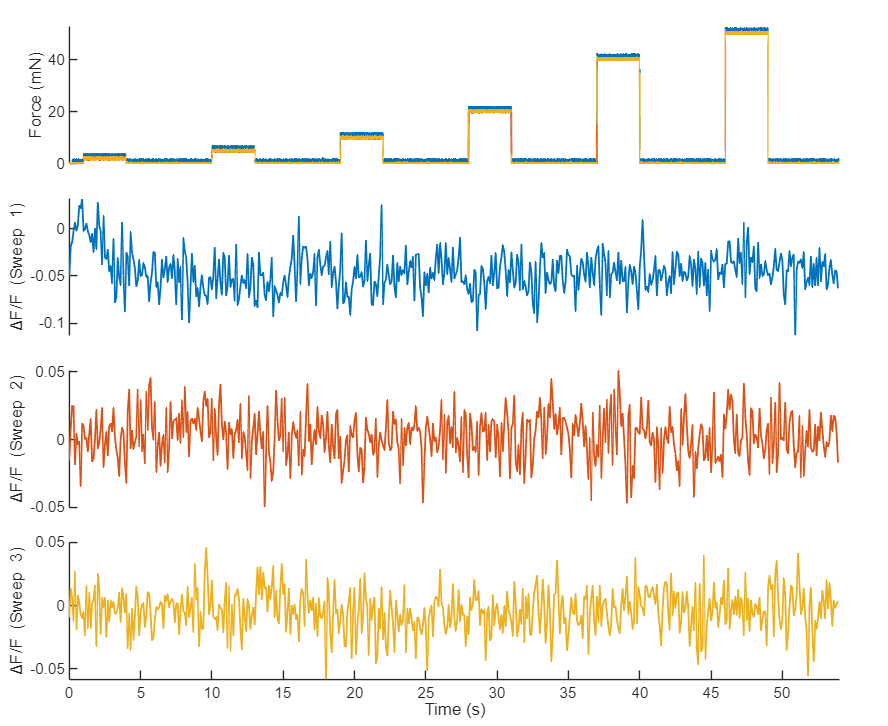

nCell = 2

fi =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


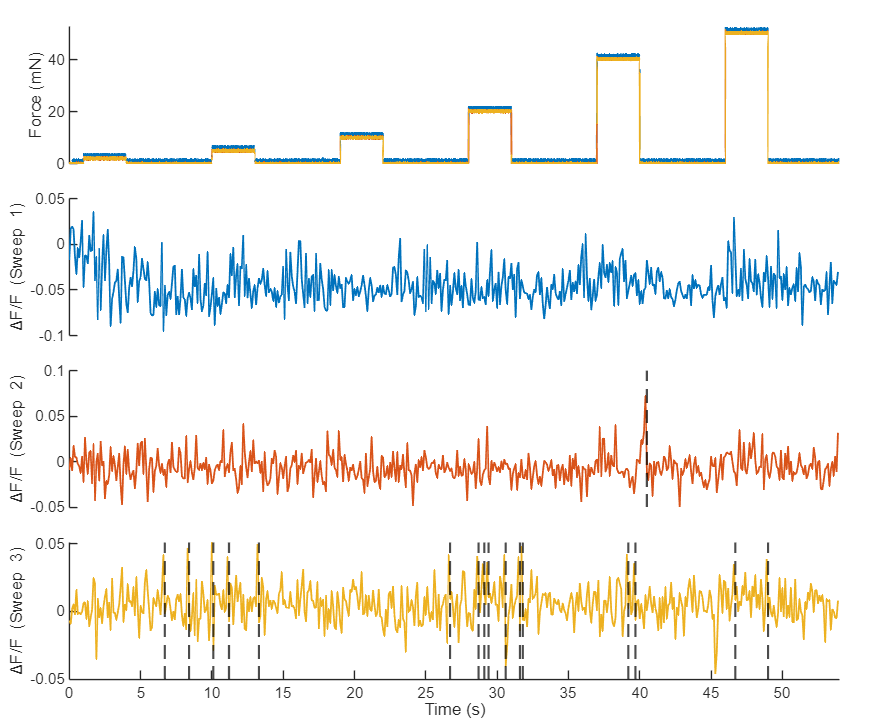

nCell = 3

fi =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


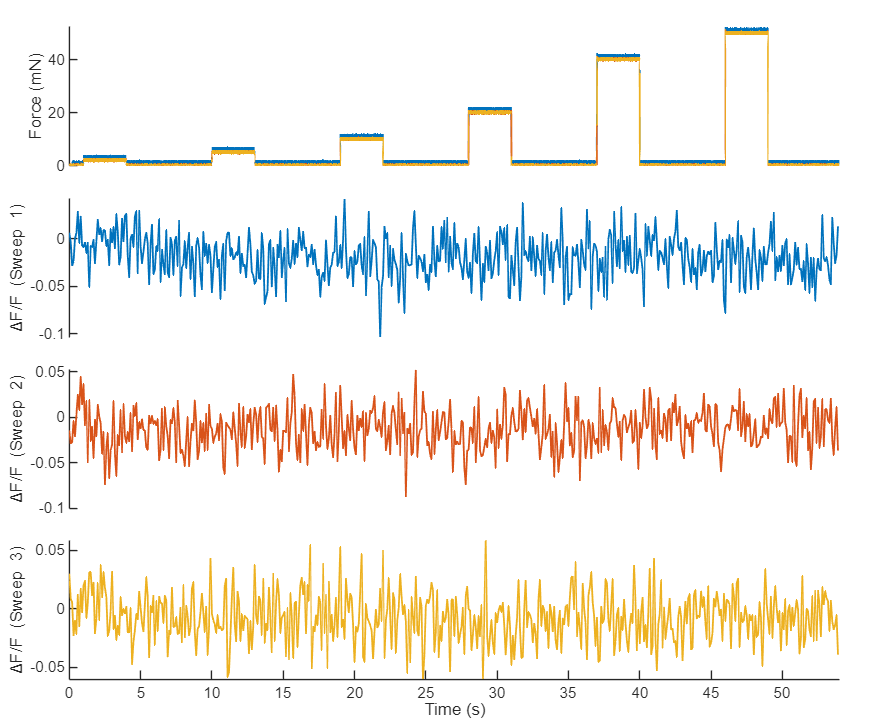

nCell = 4

fi =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


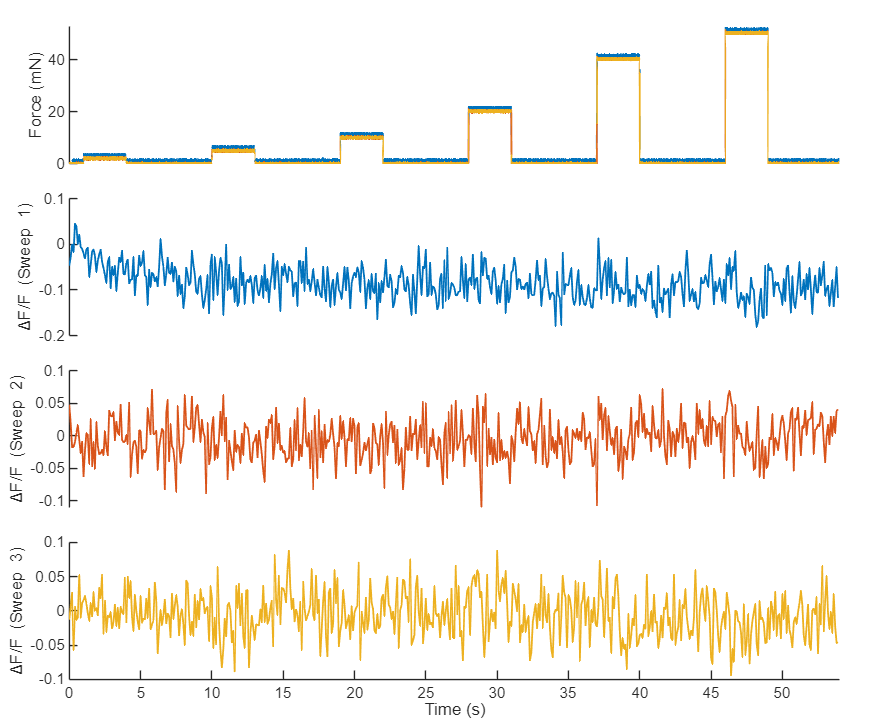

nCell = 5

fi =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


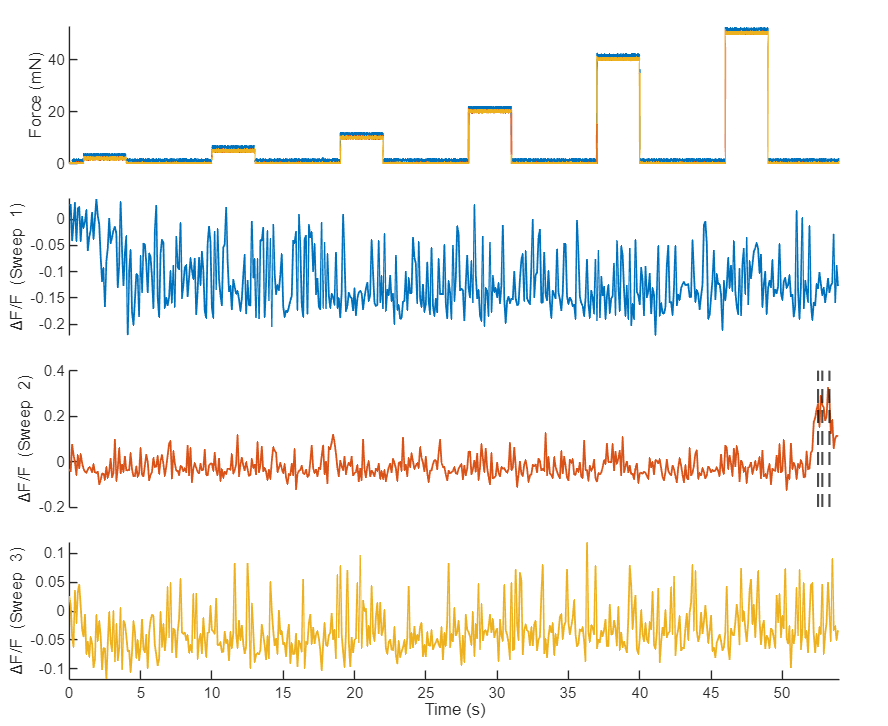

nCell = 6

fi =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


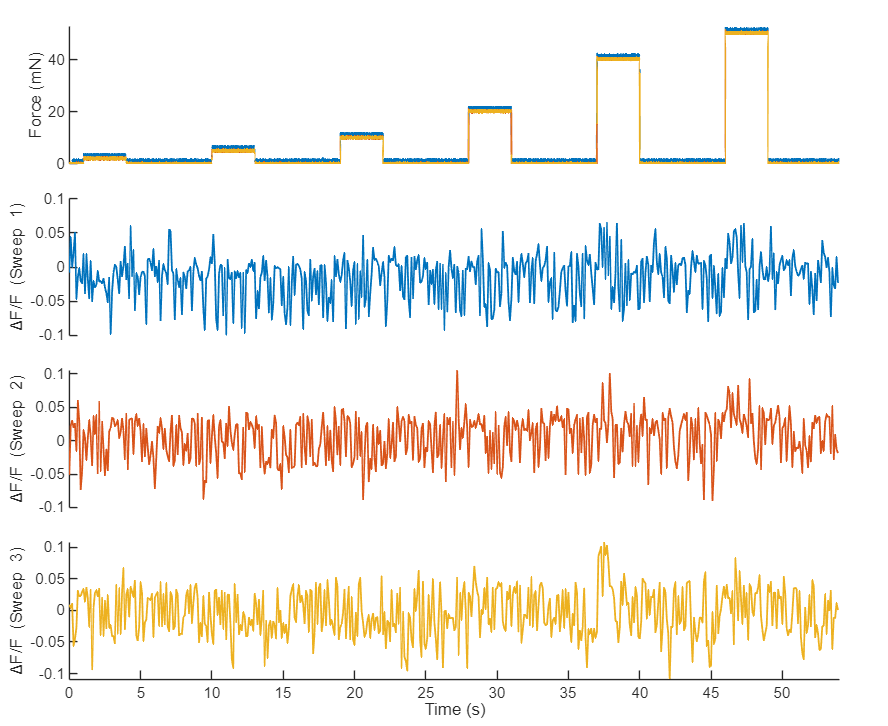

nCell = 7

fi =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


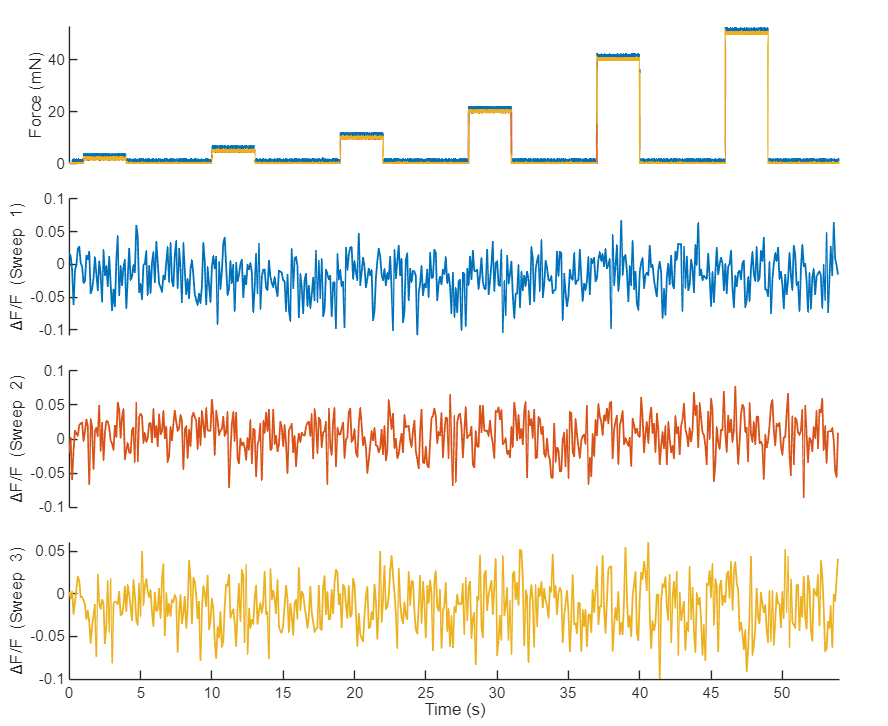

nCell = 8

fi =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


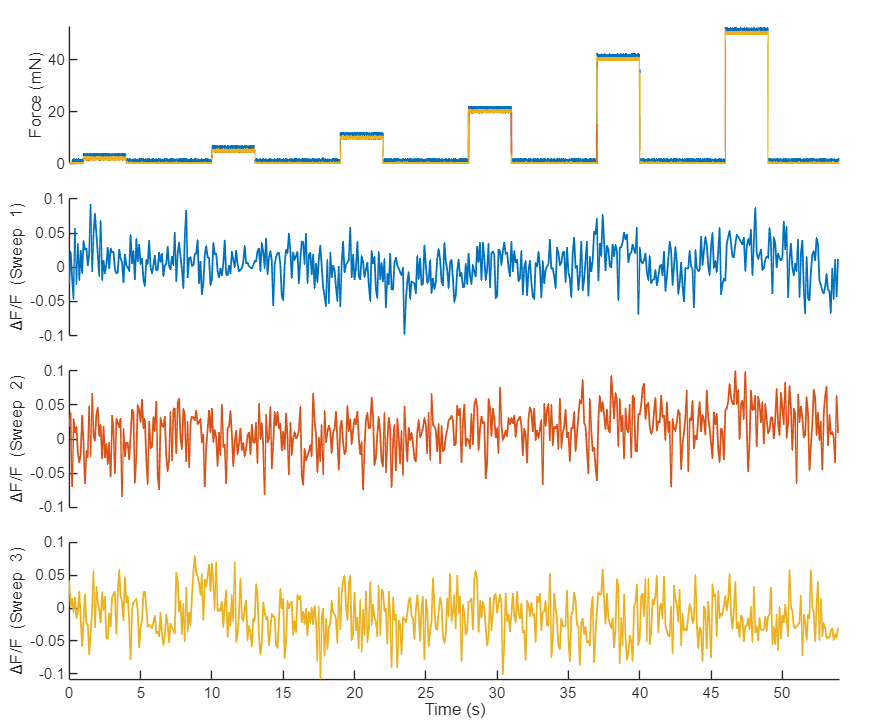

nCell = 9

fi =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


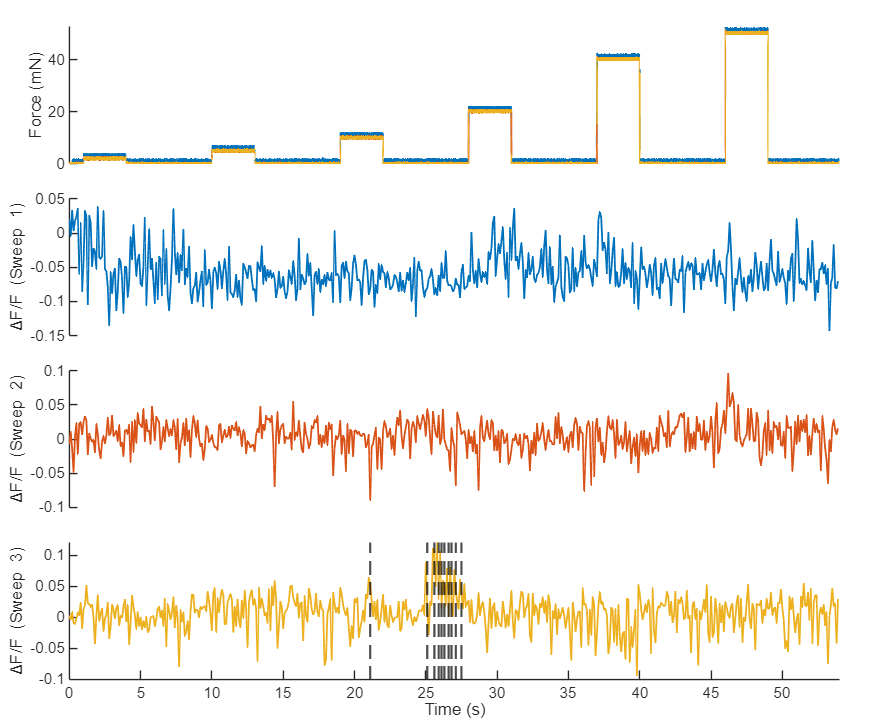

nCell = 10

fi =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


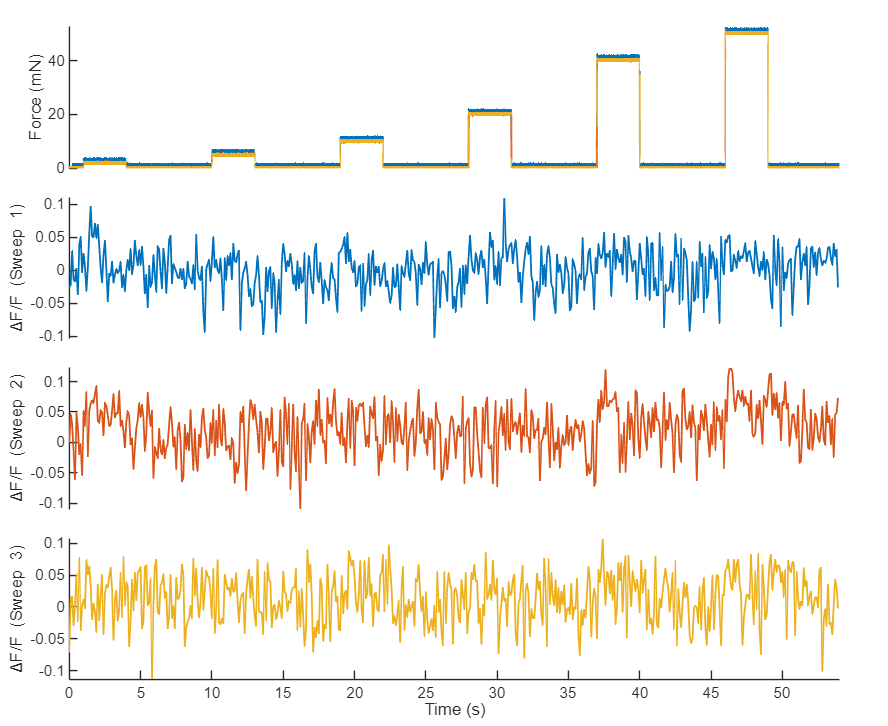

nCell = 11

fi =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


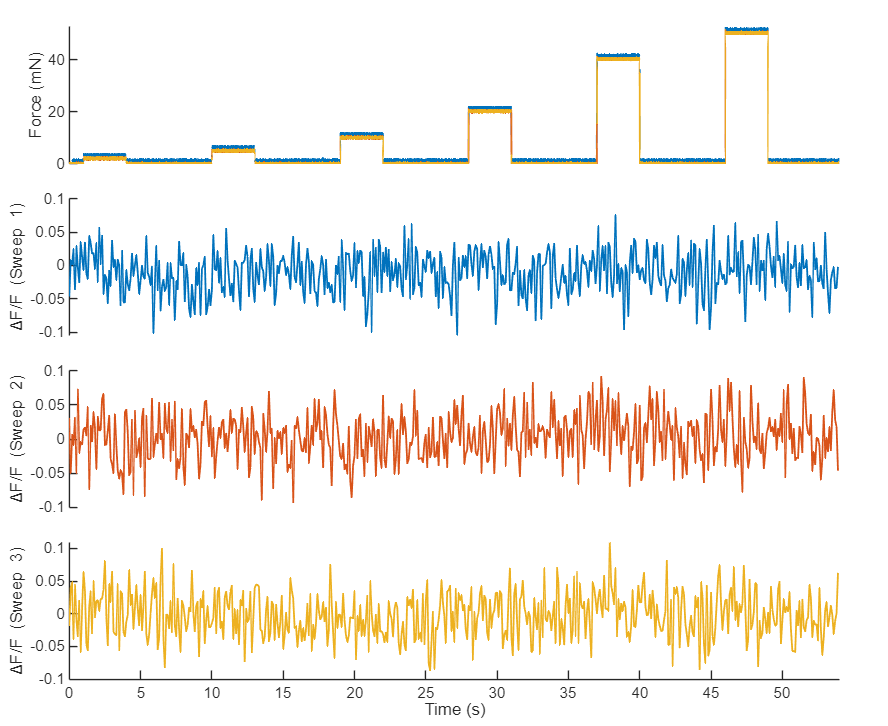

nCell = 12

fi =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


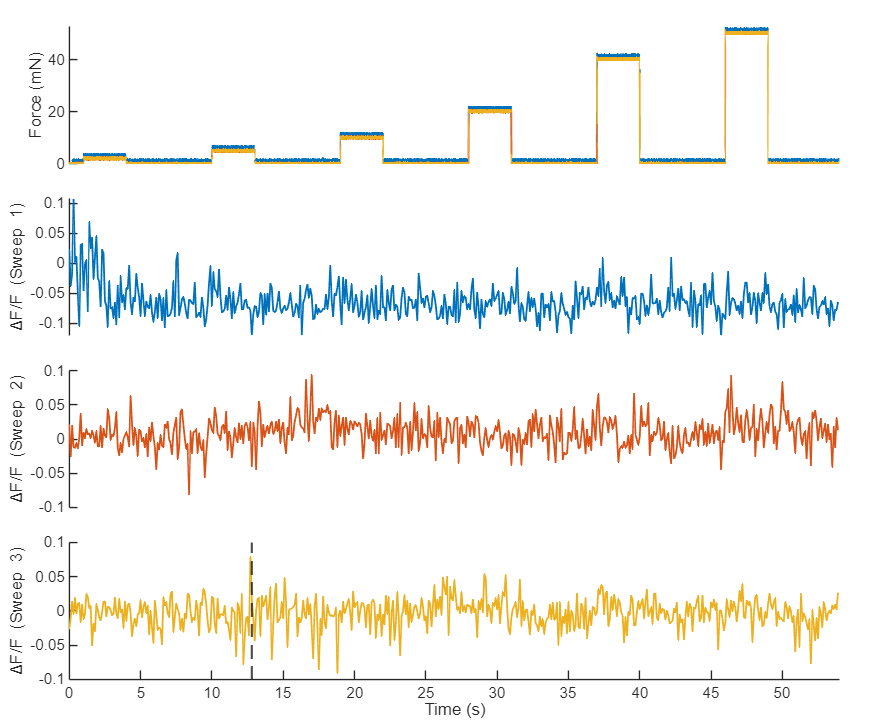

nCell = 13

fi =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


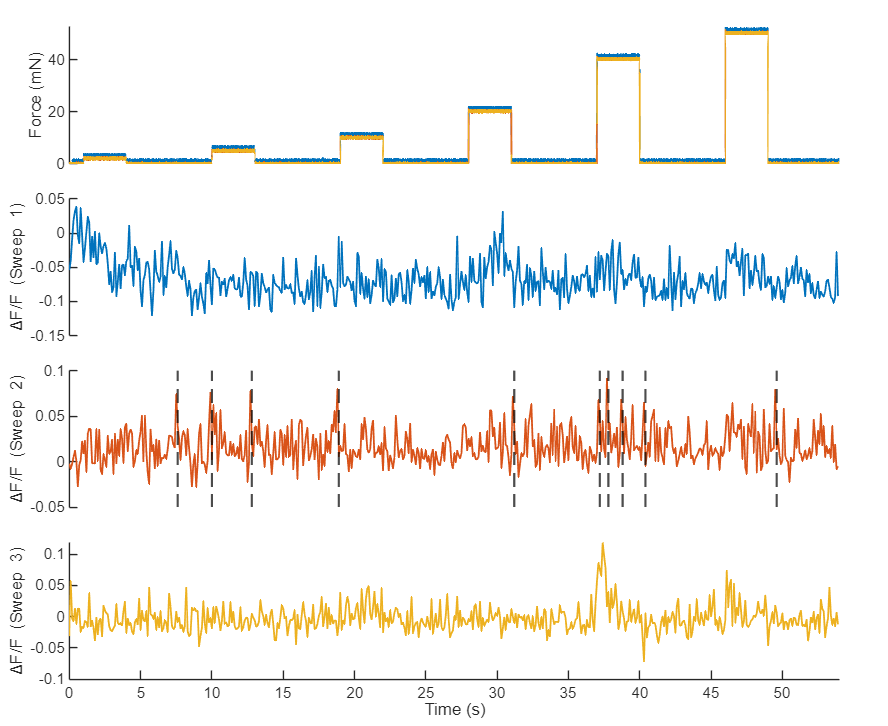

nCell = 14

fi =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


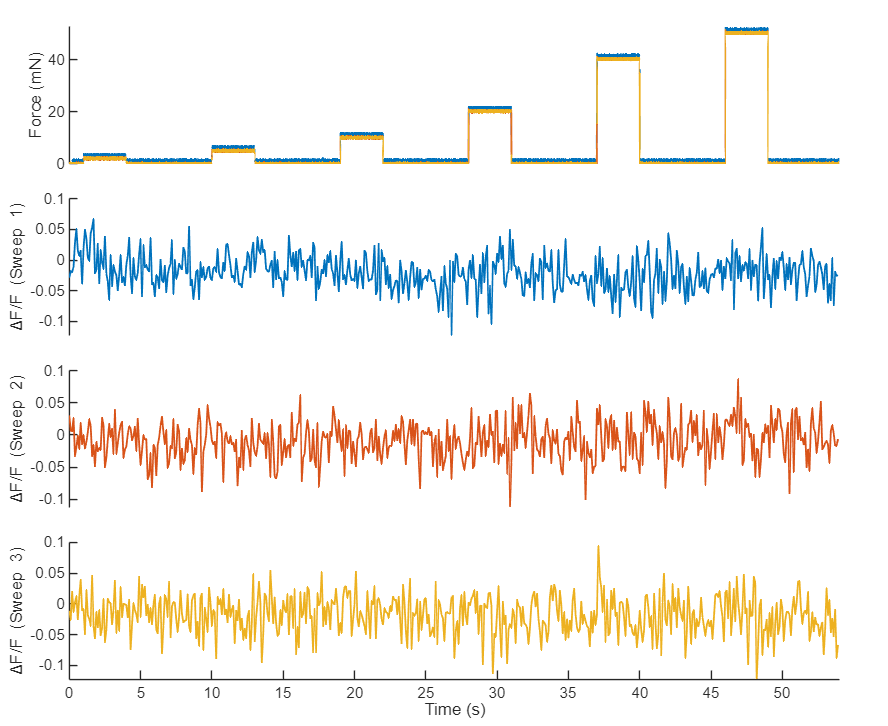

nCell = 15

fi =   Figure (17) with properties:

      Number: 17
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


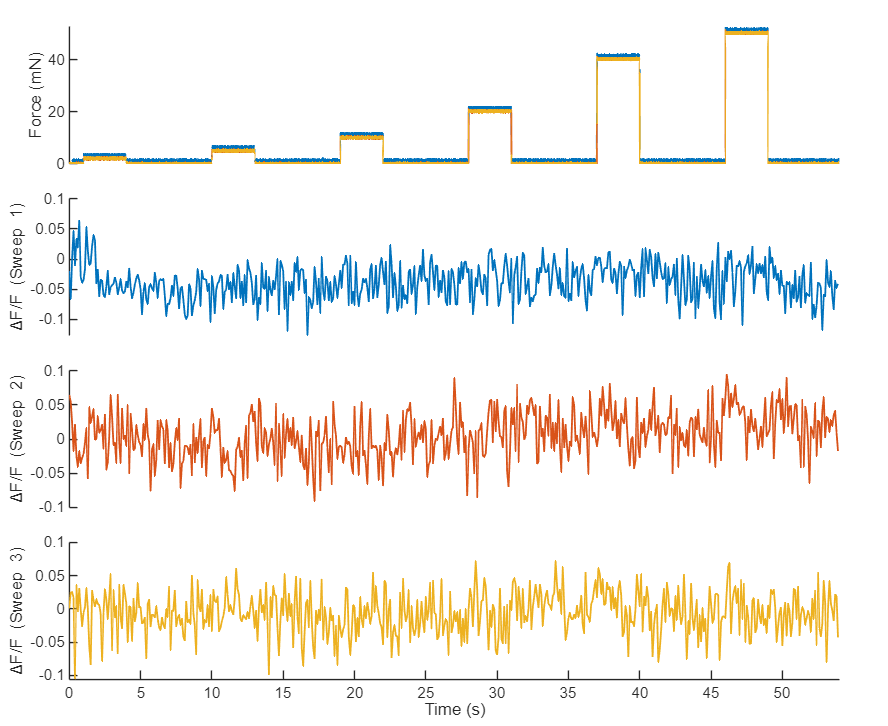

nCell = 16

fi =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


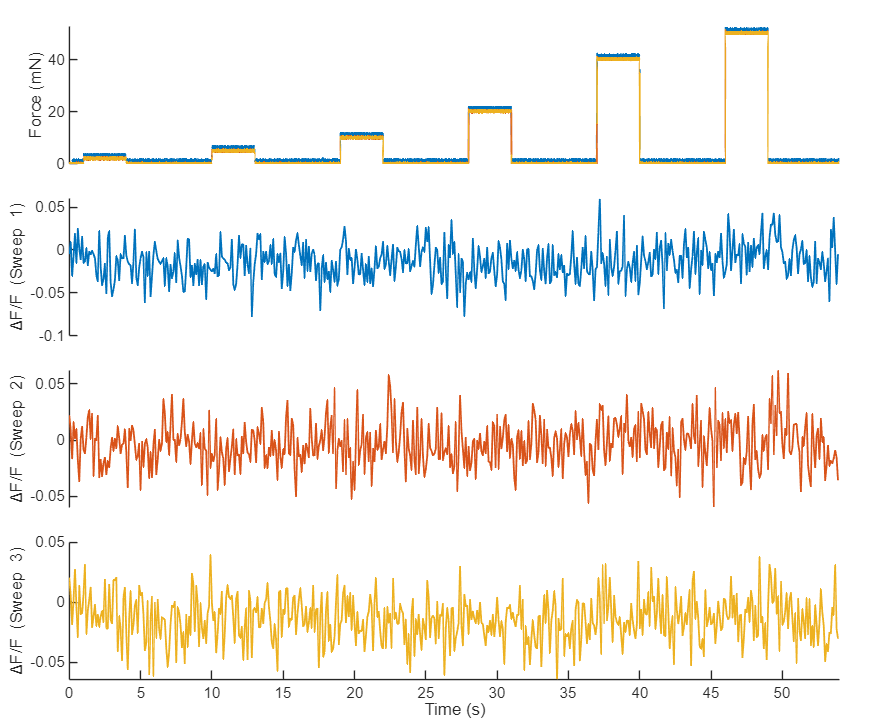

nCell = 17

fi =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


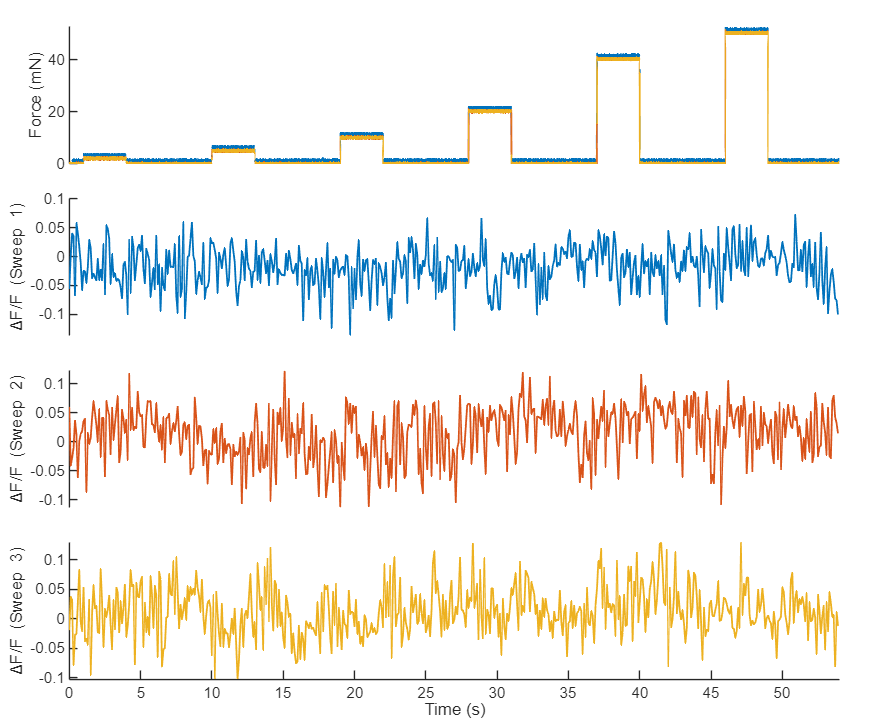

nCell = 18

fi =   Figure (20) with properties:

      Number: 20
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


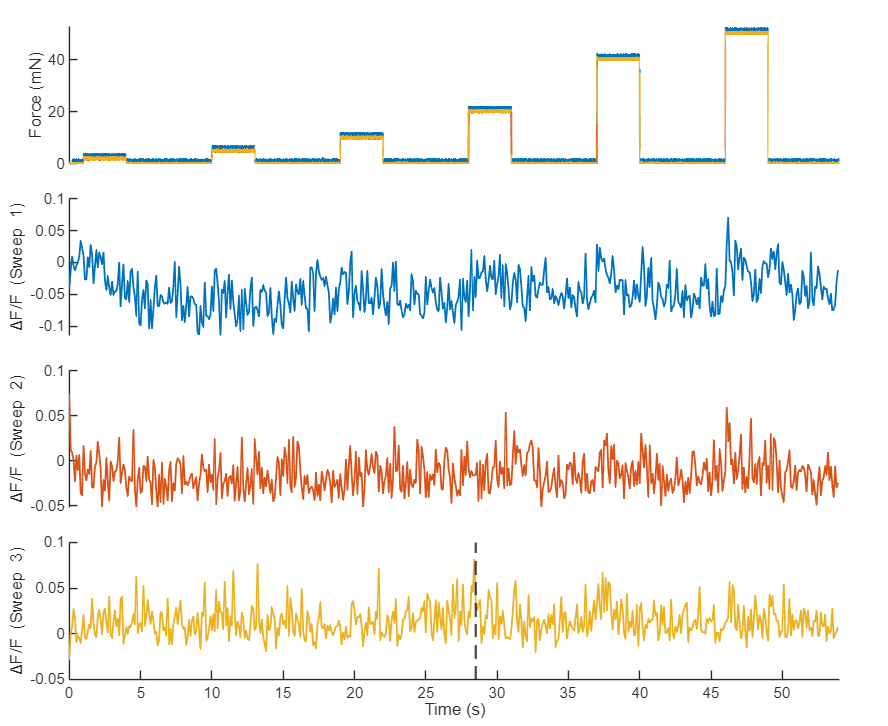

nCell = 19

fi =   Figure (21) with properties:

      Number: 21
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


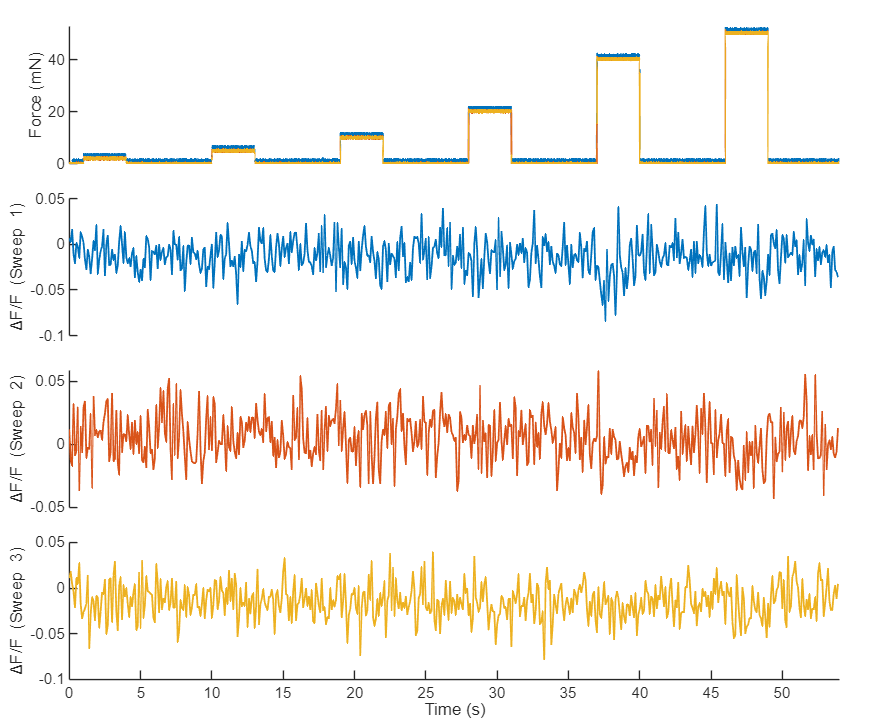

nCell = 20

fi =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


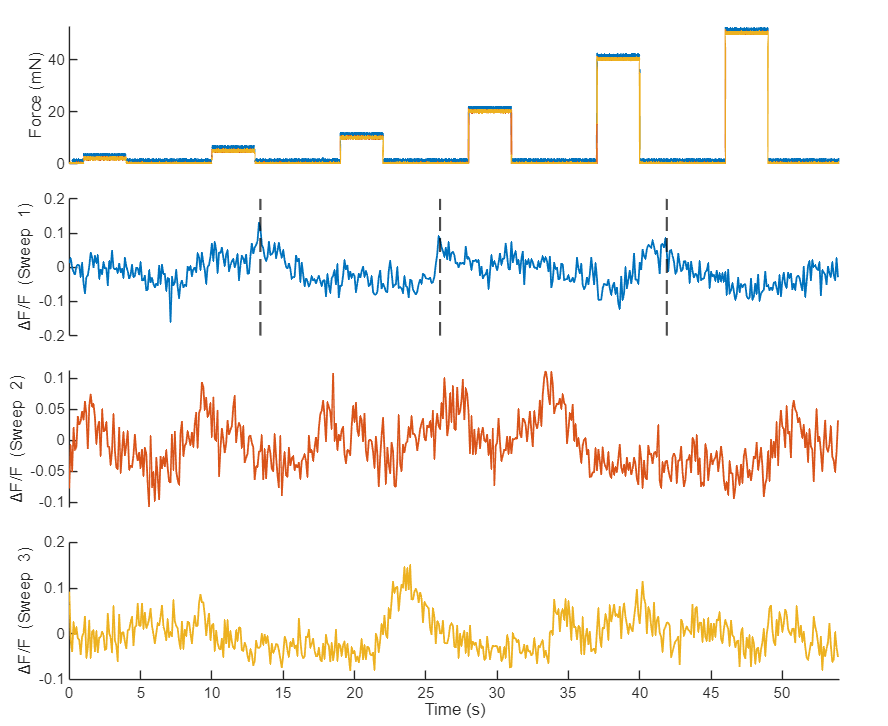

nCell = 21

fi =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


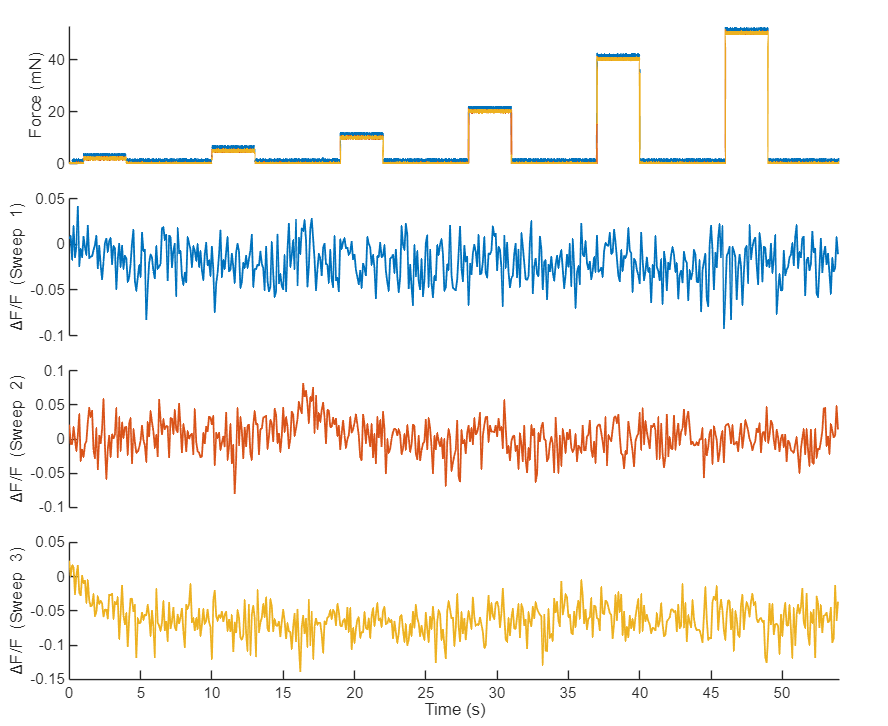

nCell = 22

fi =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


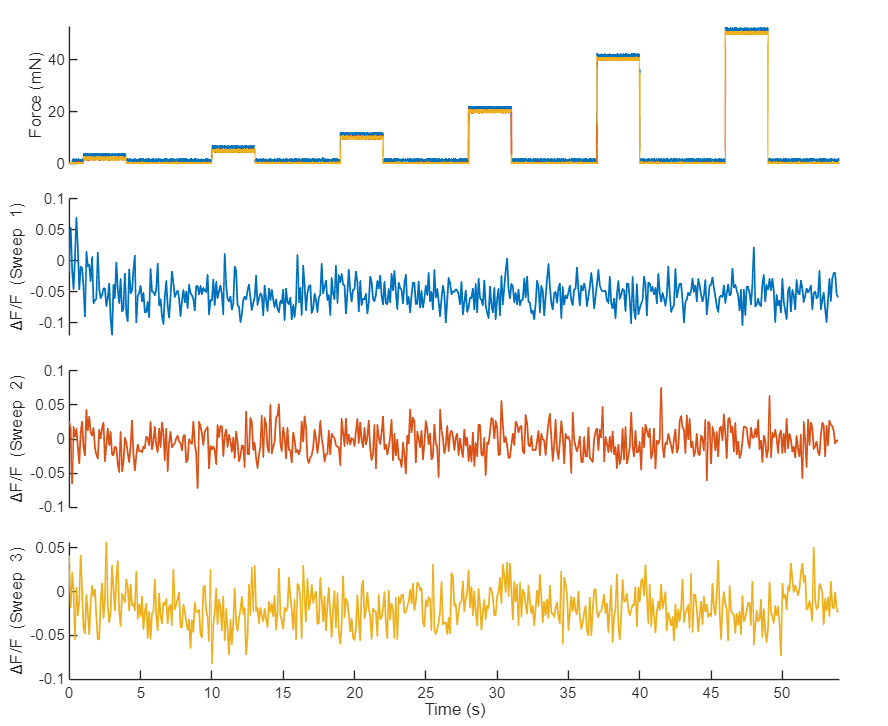

nCell = 23

fi =   Figure (25) with properties:

      Number: 25
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


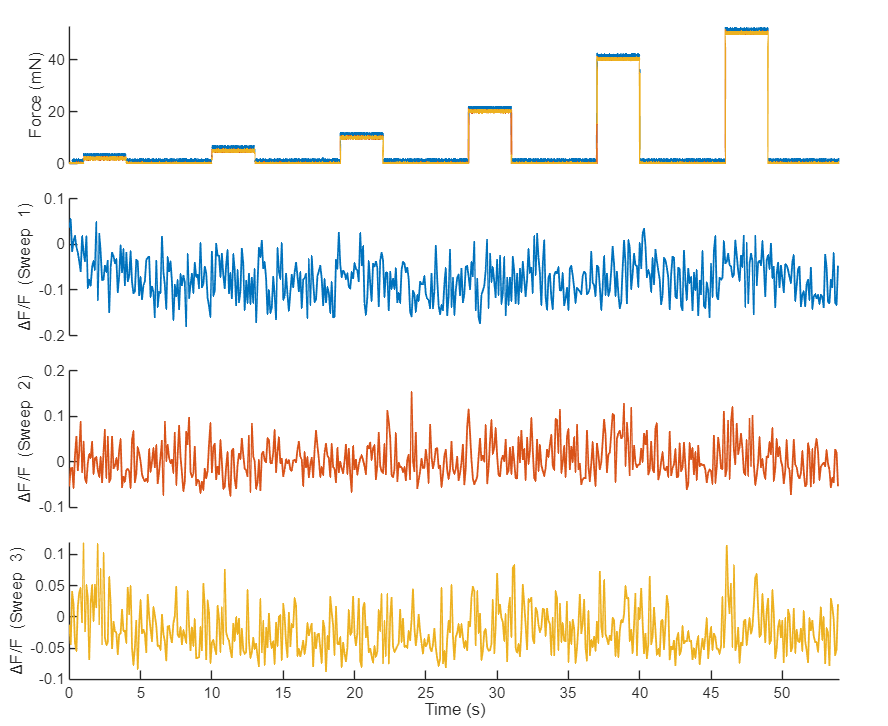

nCell = 24

fi =   Figure (26) with properties:

      Number: 26
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


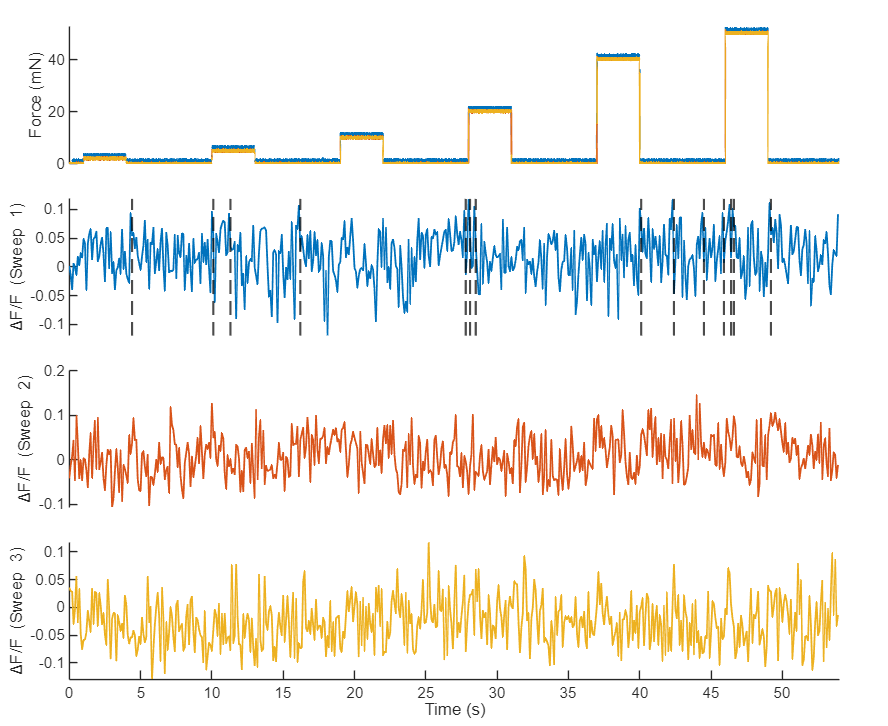

nCell = 25

fi =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


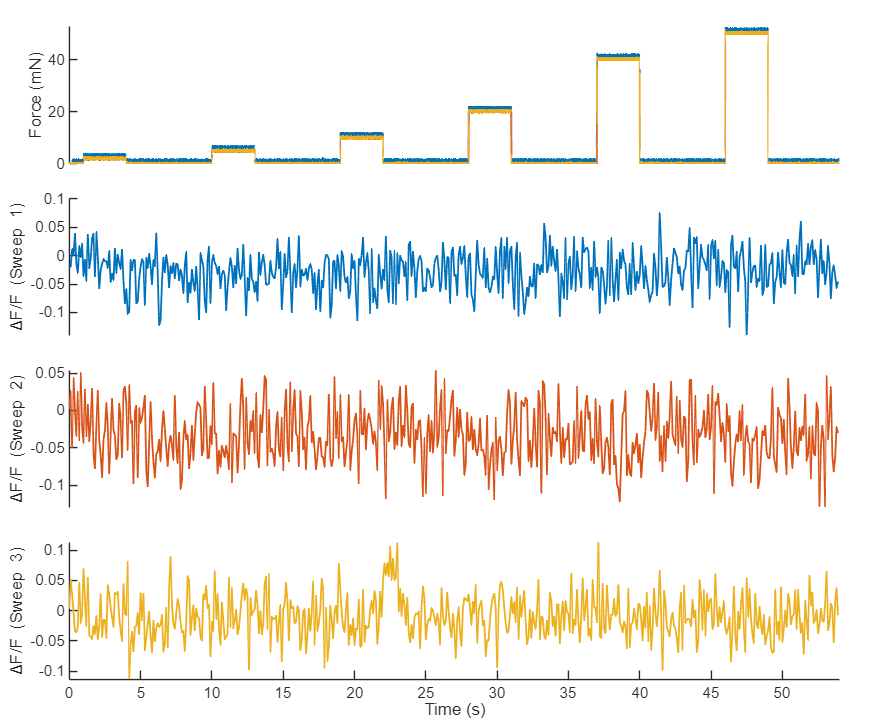

nCell = 26

fi =   Figure (28) with properties:

      Number: 28
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


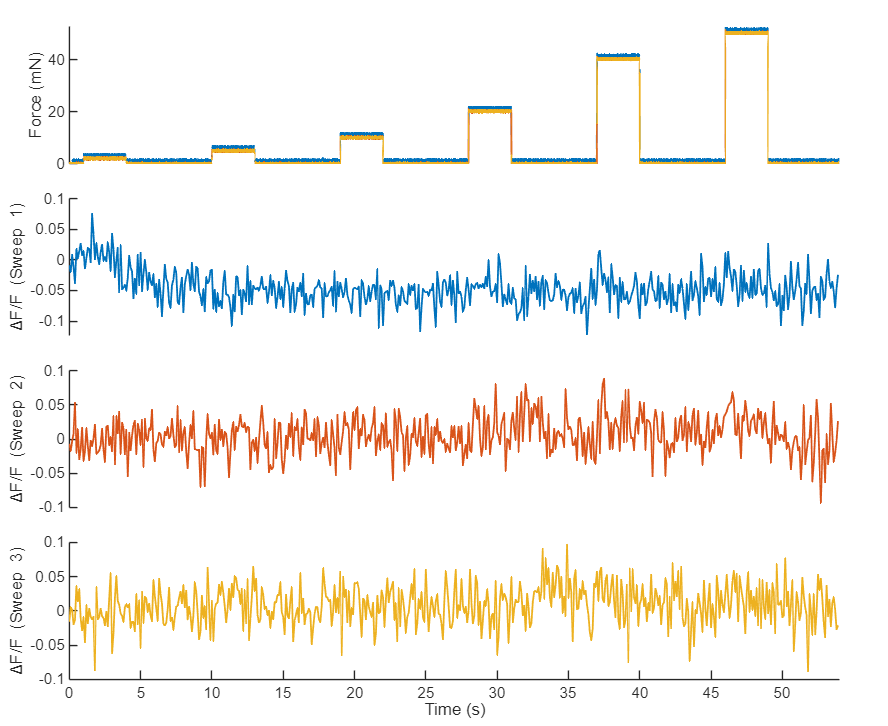

nCell = 27

fi =   Figure (29) with properties:

      Number: 29
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


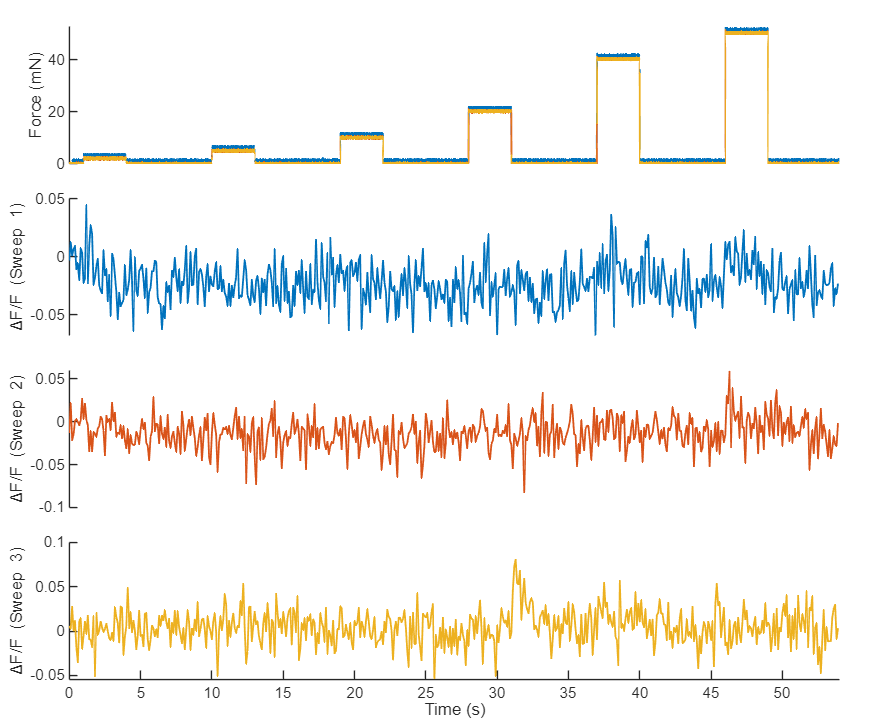

nCell = 28

fi =   Figure (30) with properties:

      Number: 30
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1100 900]
       Units: 'pixels'

  Show all properties


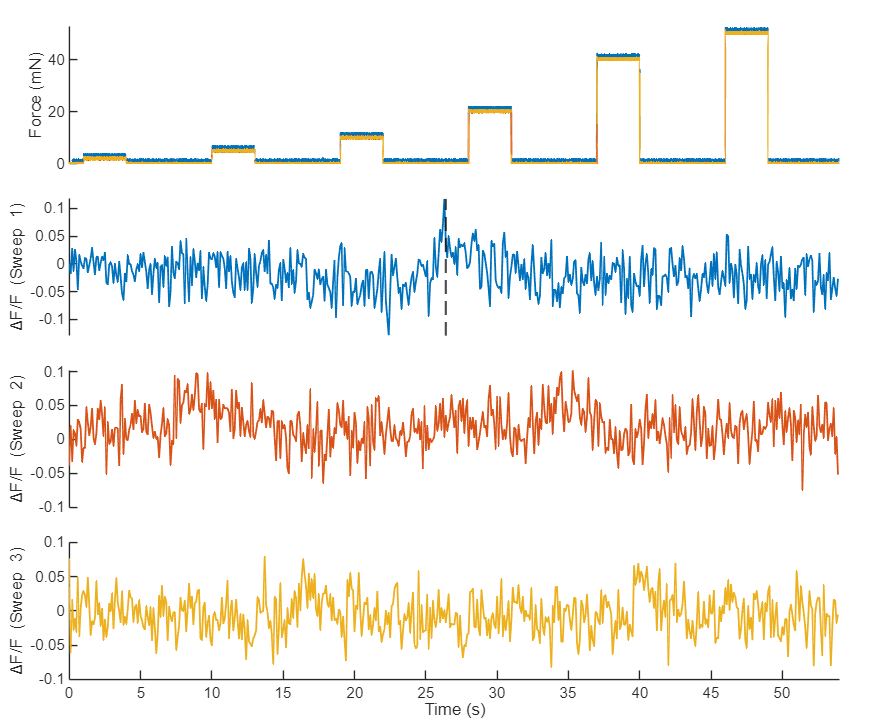

% ---- frames ----
nCells = [1:size(normDeltaF,2)];
nStd = 5;
winSamp = round((indentTime-1)*Fs);
All_cell_min_Force = struct();
forces = intensities * voltageConversion;
vibFolder = strcat(path,filename(1:end-4)) ;
if ~exist(vibFolder, 'dir')
    mkdir(vibFolder);
end
out = regexp(vibFolder, '(?<=calcium\\)(.*?)(?=\\preprocess)', 'match', 'once');

threshName = fullfile(vibFolder, [out,'_Neuron',sprintf('%d', nCells),'_threshStepSum.mat']);

for j = 1: numel(nCells)
    nCell = nCells(j)
    normDeltaFncell = normDeltaF(:,nCell);
    m = length(normDeltaFncell);
    nUnit = floor(m/numSweeps);
    newDeltaF = zeros(nUnit, numSweeps);
    crossFrameAbs = nan(nUnit,numSweeps);
    minForce = NaN;
    idx_perSweep = nan(numSweeps,1);
    for i = 1:numSweeps
        if i*nUnit < size(normDeltaF,1)
            newDeltaF(:, i) = normDeltaFncell((i-1) * nUnit +1 : i * nUnit) ;
        else
            newDeltaF(:, i) = [normDeltaFncell((i-1) * nUnit +1 : end); zeros(i * nUnit - size(normDeltaF,1), 1)];
        end
        % [~, newDeltaF(:, i), ~] = RobustDetrend(newDeltaF(:, i), 6, 0.975);
        newDeltaF(:,i) = newDeltaF(:,i) - mean(newDeltaF(1:baseline * fps, i)); %correct the baseline
        baselineMean = mean(newDeltaF(1:baseline * fps, i));
        baselineStd = std(newDeltaF(1:baseline * fps, i));
        threshold = baselineMean + nStd*baselineStd;
        above = newDeltaF(:,i) > threshold;
        all_above_idx = find(above);  %Define when the neuron signal is above the set threshold
        if ~isempty(all_above_idx)  %Find the first of the consecutive frames that is above the threshold
            runStartIdx = all_above_idx([true; diff(all_above_idx) ~= 1]);
            crossFrameAbs(runStartIdx,i) = runStartIdx; 
        end
        if ~all(isnan(crossFrameAbs(:,i))) %Find the minimum force above threshold [rolling window for force to get estimates]
            min_validIdx = min(crossFrameAbs(~isnan(crossFrameAbs(:,i)), i));
            min_forceIdx = round((min_validIdx-1)/fps*Fs)+1;
            min_forceIdx = max(1, min(min_forceIdx, size(forceSplit,1)));
            i1 = max(1, min_forceIdx - winSamp);
            i2 = min(size(forceSplit,1), min_forceIdx + winSamp);
            minForce_temp = max(forceSplit(i1:i2, i), [], 'omitnan') * voltageConversion;
            [~, idx_perSweep(i)] = min(abs(forces - minForce_temp)); 
        end
    end
    validIdx = idx_perSweep(~isnan(idx_perSweep));  %Get the mode for the three sweeps and define minForce
    idxMode = mode(validIdx);
    if sum(validIdx == idxMode) >= 2
        minForce = forces(idxMode);
    end
    if any(validIdx ~= idxMode)
        warning('Neuron %d: sweeps disagree: %s', nCell, mat2str(forces(validIdx)'));
    end
    fieldname_cell = matlab.lang.makeValidName(sprintf('Neuron%d', nCell));
    All_cell_min_Force.(fieldname_cell) = minForce;
    
    tForce = (0:size(forceSplit,1)-1) / Fs;
    tCa    = (0:size(newDeltaF,1)-1) / fps;
    ax = gobjects(numSweeps+1,1);

    fi = figure('Units','pixels','Position',[100 100 1100 900])
    tl = tiledlayout(numSweeps+1,1,'TileSpacing','compact','Padding','compact');
    cmap = lines(numSweeps);

    % ================= TOP: FORCE (all sweeps overlaid) =================
    ax(1) = nexttile;
    hold on
    for i = 1:numSweeps
        p = plot(tForce, forceSplit(:,i)*voltageConversion, 'LineWidth', 1);
        p.Color = [cmap(i,:) 0.5];   % transparency
    end
    ylabel('Force (mN)')
    ylim([0, max(intensities)*voltageConversion*1.05])
    % title('Force')
    box off
    hold off

    % ================= BOTTOM: CALCIUM (all sweeps overlaid) =================
    for i = 1:numSweeps
        ax(i+1) = nexttile;
        hold on
        p = plot(tCa, newDeltaF(:,i), 'LineWidth', 1);
        p.Color = [cmap(i,:) 0.8];   % transparency
        validIdx = crossFrameAbs(~isnan(crossFrameAbs(:,i)), i);
        for k = 1:numel(validIdx)
            xline(validIdx(k)/fps, '--k', 'LineWidth', 1.2);
        end
        ylabel(['\DeltaF/F',sprintf(' (Sweep %d)',i),])
        box off
        hold off
        %ylim([0,max(newDeltaF(:,i))*1.05])
    end
    xlabel('Time (s)')
    % title(sprintf('Neuron %d calcium', nCell))
    linkaxes(ax, 'x');
    xlim(ax(1), [0 max(round(tCa))]);
    for k = 1:length(ax)-1
        ax(k).XColor = 'none';   % removes ticks + labels + axis line
    end
    figurename = fullfile(vibFolder,[sprintf('Neuron%d', nCell),'_ForceAligned_stepInd.pdf']);
    exportgraphics(fi, figurename,"Resolution",300);
end

save(threshName,'All_cell_min_Force');

## Select specific neuron and trace for one plot

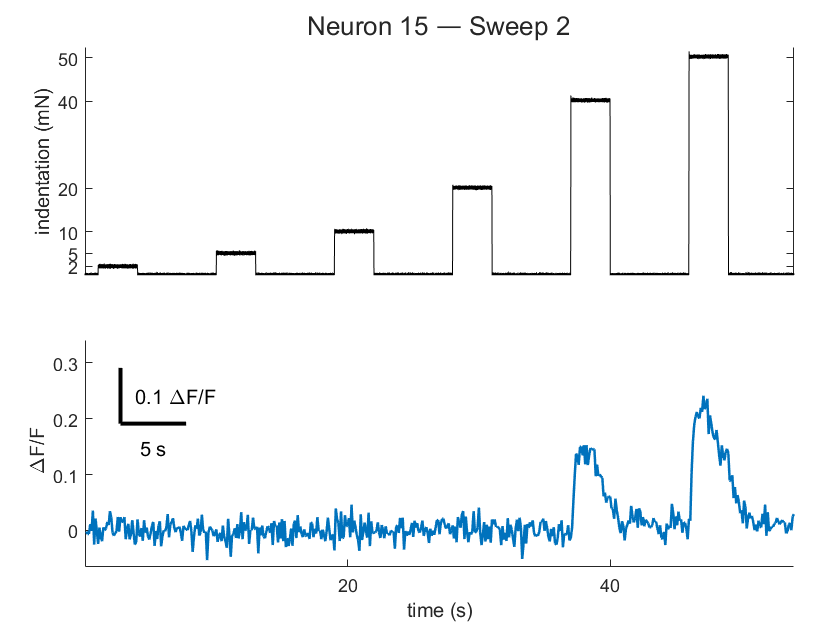

% ==== PARAMETERS ====
selectedNeuron = 13;    % which neuron
selectedSweep  = 2;    % which sweep

% ==== Get full trace for this neuron ====
normDeltaFncell = normDeltaF(:, selectedNeuron);
m = length(normDeltaFncell);
nUnit = floor(m/numSweeps);   % frames per sweep

% ==== Directly index into the chosen sweep ====
StartIdx = (selectedSweep-1)*nUnit + 1;
EndIdx   = StartIdx + nUnit - 1;
if EndIdx > m
    thisTrace = normDeltaFncell(StartIdx:end);
else
    thisTrace = normDeltaFncell(StartIdx:EndIdx);
end

% baseline subtract
thisTrace = thisTrace - mean(thisTrace(1:baseline*fps));

% ==== PLOT (force top, selected trace bottom) ====
fh = figure; set(fh,'Color','w'); set(fh,'Visible','on');
t = tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

% --- Force (top) ---
axForce = nexttile(t,1);
% If you have force for each sweep, show the matching one; otherwise use (:,1)
if size(forceSplit,2) >= selectedSweep
    p = plot(forceSplit(:, selectedSweep)*voltageConversion, 'Color', 'k');
else
    p = plot(forceSplit(:, 1)*voltageConversion, 'Color', 'k');
end
xlim([0 size(forceSplit,1)]);
ylabel("indentation (mN)");
set(axForce,'XColor',[1 1 1]); % hide x ticks
% your original y-limit/ticks logic
yticks(forces);
yticklabels(string(forces));
ylim([0, max(intensities)*voltageConversion*1.05])

% --- Selected calcium trace (bottom) ---
axTrace = nexttile(t,2);
plot(thisTrace, 'LineWidth', 1.25, 'Color', cmap(1,:)); hold on
xlim([0 nUnit]);
yl = [min(normDeltaFncell(:))-0.01, max(thisTrace) + 0.1];
ylim(yl);
set(axTrace,'XTick',200:200:700,'XTickLabel',["20" "40" "60"]); % adjust if needed
xlabel("time (s)"); ylabel(' \DeltaF/F');
box off

% --- Corner scale bars: vertical ΔF/F and horizontal 5 s ---
% Choose corner anchor inside the bottom plot
x0 = round(0.05*nUnit);         % 5% from left; tweak as needed
y0 = yl(2) - 0.15;              % a bit above bottom

% vertical (ΔF/F). Keep your heuristic; swap for fixed value if you prefer.
if max(normDeltaFncell)/4 > 0.1
    scaleLengthY = floor(max(normDeltaFncell)/4 * 10) / 10;
else
    scaleLengthY = 0.1;
end
plot([x0 x0], [y0 y0+scaleLengthY], 'k', 'LineWidth', 2)
text(x0+0.02*nUnit, y0+scaleLengthY/2, ...
    [num2str(scaleLengthY) ' \DeltaF/F'], ...
    'VerticalAlignment','middle','HorizontalAlignment','left')

% horizontal (5 s)
scaleLengthX = 5 * fps;                             % frames for 5 seconds
plot([x0 x0+scaleLengthX], [y0 y0], 'k', 'LineWidth', 2)
text(x0+scaleLengthX/2, y0-0.02, '5 s', ...
    'VerticalAlignment','top','HorizontalAlignment','center')

% Title
sgtitle(sprintf('Neuron %d — Sweep %d', nCell, selectedSweep));
figureName_selected = strcat(vibFolder,"\Aligned Neuron",num2str(selectedNeuron)," step indentation example trace.pdf");
exportgraphics(fh, figureName_selected,"Resolution",300);